# Actividad #9

**Carga Masiva (data folder) y Visualización de Datos desde Archivos CSV**

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

- Dataset: [Open Energy Data Initiative (OEDI)](https://data.openei.org/)

- [Photovoltaic Data Acquisition (PVDAQ) Public Datasets](https://data.openei.org/s3_viewer?bucket=oedi-data-lake&prefix=pvdaq%2F2023-solar-data-prize%2F2105_OEDI%2Fdata%2F)

## Descripción:

##  Objetivos:

- **Configurar una estructura de carpetas eficiente** para el manejo de librerías y datasets externos en MATLAB.

- **Detectar y cargar automáticamente múltiples archivos CSV** desde un directorio de trabajo.

- **Unificar y consolidar datos reales de mediciones fotovoltaicas** en una sola tabla para su análisis.

- **Extraer dinámicamente las variables contenidas** en los datasets sin necesidad de codificación manual.

- **Visualizar múltiples señales medidas en función del tiempo**, facilitando la interpretación de fenómenos fotovoltaicos.

## Tipo de Dataset a utilizar:

- Cada columna representa una variable y cada fila representa una muestra (frecuencia de mestreo constante)

- La primera columna es el TimeStamp. Ejemplo: 'dd-MMM-yyyy HH:mm:ss.SSS'

- El arhivo debe estar en formato **.csv**, si es otro formato de debera convertir a .csv. Ejemplo: si es **.parqet**, se lo convierte con esta pagina [https://table.studio/convert/parquet/to/csv](https://table.studio/convert/parquet/to/csv)

- Si existen multiples archivos .csv, estos se deberan colocar en la carpeta data, siempre que esten relacionadas a un mismo sistema. **Ejemplo de regresion**: consumo_enero_2025.csv, consumo_febrero_2025.csv, etc. **Ejemplo de clasificacion**: consumo_casa_enero_2025.csv, sonsumo_escuela_enero_2025.csv, etc.

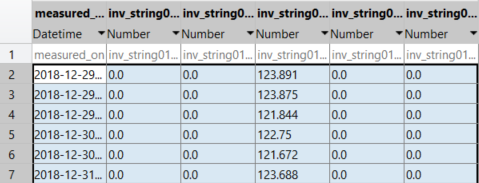

## **Copia la actividad en tu respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if true
    % repositorio -> respaldo
    git_sse(miRespaldo)

filename = 5×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


else

maxFiles = 5

    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))
end

pathFile = '.\data\Copy_2_of_2105_inv01_data.csv'

pathFile = '.\data\Copy_3_of_2105_inv01_data.csv'

pathFile = '.\data\Copy_4_of_2105_inv01_data.csv'

pathFile = '.\data\2105_inv01_data.csv'

pathFile = '.\data\Copy_of_2105_inv01_data.csv'

## Desarrollo de la Actividad

#### **Paso 1: Borrar variables en el workspace y limpiar cmd**

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window

#### Paso 2: Configuración de carpeta ./src para librerias

addpath(genpath('./src'));

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×6 cell}
    VariableDescriptions: {1×6 cell}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


#### Paso 3: Configuración de carpeta ./data para datasets

datapath = fullfile('./data/');

#### Paso 4: Buscar nombres de archivos .csv en ./data

filename = FindCSV(datapath)

VariableNames = 1×6 cell array
    {'measured_on'}    {'inv_string01_ac_output__kwh__inv_150164'}    {'inv_string01_ac_output__power_factor__inv_150165'}    {'inv_string01_ac_voltage__v__inv_150163'}    {'inv_string01_dc_voltage__v__inv_150162'}    {'inv_string01_temperature__c__inv_150166'}


maxFiles = size(filename,1)

#### Paso 5: Cargar automaticamente todos los archivos csv desde ./data

allData = [];
for i=1:maxFiles
    nameFile = filename(i).name;
    pathFile = strcat(datapath, nameFile)
    rawData = fLoad_dataset(pathFile);
    allData = [allData; rawData];
end
clear rawData nameFile filename; 

#### Paso 6: Extraer y graficar las variables

allData.Properties

samples = 121610

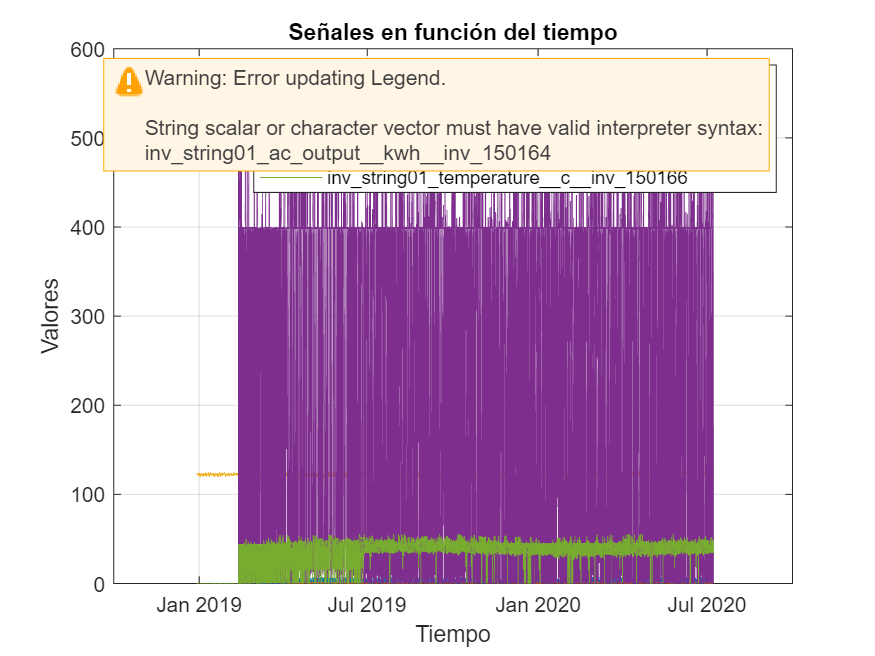

t = datetime(allData.measured_on);
VariableNames = allData.Properties.VariableNames
MaxVariables = size(VariableNames,2);

% 2 por que el timeStamp ya fue leido
dataArray = [];
for i=2:MaxVariables

    variable = allData{:,VariableNames(i)};
    dataArray = [dataArray, variable];
end

figure;
maxSamples = size(dataArray,1);
samples = 121610
plot(t(1:samples,:),dataArray(1:samples,:)); % las 1k primeras filas

legend(string(VariableNames(2:end)));
xlabel('Tiempo');
ylabel('Valores');
title('Señales en función del tiempo');
grid on;